## 等加速度直線運動の公式

### (1) $v=v_0 +at$

### (2) $x=v_0 t+\frac{1}{2}{at}^2$

### (3) $v^2 -{v_0 }^2 =2ax\;$

T = 0.1; %サンプリング周期
t = 0:T:10;%時刻t

robot_pos = [0 ;0 ;0];%飛行体の初期位置[x y z]

%飛行体の各座標方向の加速度
ax = randn(1,length(t)-1);%x方向の加速度[m/s^2]
ay = randn(1,length(t)-1);%y方向の加速度[m/s^2]
az = randn(1,length(t)-1);%z方向の加速度[m/s^2]

%時刻０の初速度[m/s]
vx0 = 0

vx0 = 0

vy0 = 0

vy0 = 0

vz0 = 0

vz0 = 0


for i = 2:length(t)
        
    %移動距離の算出(2)式
    move_x = vx0*T + (ax(i-1)*T^2)/2;
    move_y = vy0*T + (ay(i-1)*T^2)/2;
    move_z = vz0*T + (az(i-1)*T^2)/2;
    
    %現在の位置の算出：1時刻前の位置に移動距離を加算
    robot_pos(1,i) = robot_pos(1,i-1) + move_x;
    robot_pos(2,i) = robot_pos(2,i-1) + move_y;
    robot_pos(3,i) = robot_pos(3,i-1) + move_z;
    
    %サンプリング周期の期間の速度を加速度より算出(1)式
    vx = vx0 + ax(i-1)*T; 
    vy = vy0 + ay(i-1)*T;
    vz = vz0 + az(i-1)*T;
    
    %現在の速度が１時刻後の初速になる
    vx0 = vx;
    vy0 = vy;
    vz0 = vz;
    
end


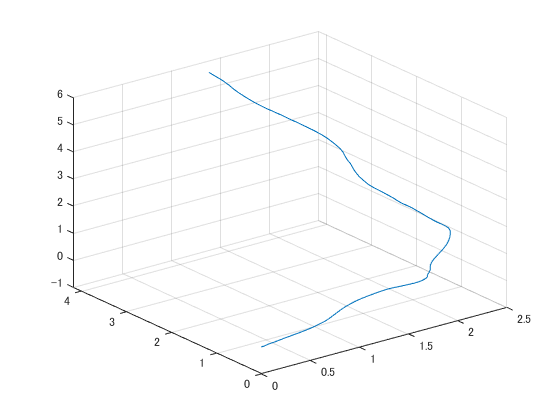

figure;
plot3(robot_pos(1,:),robot_pos(2,:),robot_pos(3,:));
grid on;

アニメーション

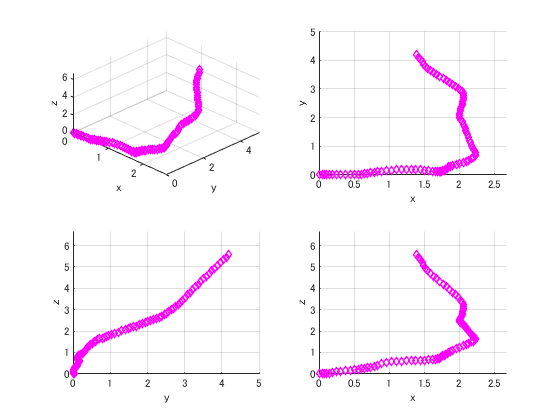

%各座標の表示サイズ
axis_x = [min(robot_pos(1,:))*1.2 max(robot_pos(1,:))*1.2];
axis_y = [min(robot_pos(2,:))*1.2 max(robot_pos(2,:))*1.2];
axis_z = [min(robot_pos(3,:))*1.2 max(robot_pos(3,:))*1.2];

for k = 1:size(robot_pos,2)
    
    
    %------軌跡を表示させる場合コメントアウト-------
%     if k <= 1
%         plot_info1 = animatedline('Marker','diamond','MarkerSize',10,'Color','m');
%         plot_info2 = animatedline('Marker','diamond','MarkerSize',10,'Color','m');
%         plot_info3 = animatedline('Marker','diamond','MarkerSize',10,'Color','m');
%         plot_info4 = animatedline('Marker','diamond','MarkerSize',10,'Color','m');
%     end
% 
%     clearpoints(plot_info1)
%     clearpoints(plot_info2)
%     clearpoints(plot_info3)
%     clearpoints(plot_info4)
%     
    %------------------------------------------------
    subplot(2,2,1)
    plot_info1 = animatedline('Marker','diamond','MarkerSize',5,'Color','m');
    axis([axis_x axis_y axis_z])
    xlabel('x')
    ylabel('y')
    zlabel('z')
    grid on
    
    x = robot_pos(1,k);
    y = robot_pos(2,k);
    z = robot_pos(3,k);
    
    addpoints(plot_info1,x,y,z);
    view(45,45)%グラフの見る視点

    %------------------------------------------------
    subplot(2,2,2)
    plot_info2 = animatedline('Marker','diamond','MarkerSize',5,'Color','m');
    axis([axis_x axis_y axis_z])
    xlabel('x')
    ylabel('y')
    zlabel('z')
    grid on;
    
    x = robot_pos(1,k);
    y = robot_pos(2,k);
    z = robot_pos(3,k);
    addpoints(plot_info2,x,y,z);
    view(0,90)%グラフの見る視点

    %------------------------------------------------
    subplot(2,2,3)
    plot_info3 = animatedline('Marker','diamond','MarkerSize',5,'Color','m');
    axis([axis_x axis_y axis_z])
    xlabel('x')
    ylabel('y')
    zlabel('z')
    grid on;
    
    x = robot_pos(1,k);
    y = robot_pos(2,k);
    z = robot_pos(3,k);
    addpoints(plot_info3,x,y,z);
    view(90,0)%グラフの見る視点
    
    %------------------------------------------------
    subplot(2,2,4)
    plot_info4 = animatedline('Marker','diamond','MarkerSize',5,'Color','m');
    axis([axis_x axis_y axis_z])
    xlabel('x')
    ylabel('y')
    zlabel('z')
    grid on;
    
    x = robot_pos(1,k);
    y = robot_pos(2,k);
    z = robot_pos(3,k);
    addpoints(plot_info4,x,y,z);
    view(0,0)%グラフの見る視点
    
    drawnow
end